Last inn Iris data

clear;
x1 = load('IrisData/class_1','-ascii'); % Iris-setosa 50x4
x2 = load('IrisData/class_2','-ascii'); % Iris-versicolor 50x4
x3 = load('IrisData/class_3','-ascii'); % Iris-virginica 50x4

Visualisering av Iris data

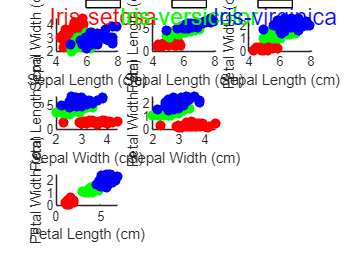

dim_labels = {'Sepal Length (cm)', 'Sepal Width (cm)', 'Petal Length (cm)', 'Petal Width (cm)'};
figure;
annotation('textbox', [0.25, 0.97, 0.1, 0.03], 'String', '• Iris-setosa', 'FontSize', 14, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'Color', 'r');
annotation('textbox', [0.5, 0.97, 0.1, 0.03], 'String', '• Iris-versicolor', 'FontSize', 14, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'Color', 'g');
annotation('textbox', [0.75, 0.97, 0.1, 0.03], 'String', '• Iris-virginica', 'FontSize', 14, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'Color', 'b');
for i = 1:3
    for j = i+1:4
        subplot(3, 3, (i-1)*3 + j-i);
        scatter(x1(:,i), x1(:,j), 'r', 'filled');
        hold on;
        scatter(x2(:,i), x2(:,j), 'g', 'filled');
        scatter(x3(:,i), x3(:,j), 'b', 'filled');
        xlabel(dim_labels{i});
        ylabel(dim_labels{j});
    end
end
hold off;

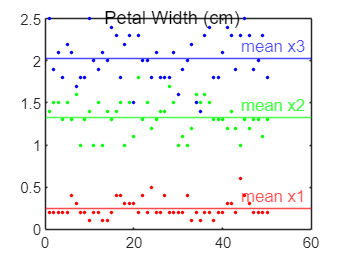


figure;
sgtitle("Petal Width (cm)")
plot(x1(:,4),'.r');
hold on;
plot(x2(:,4),'.g');
plot(x3(:,4),'.b');
yline(mean(x1(:,4)),'Label',"mean x1",'Color','r');
yline(mean(x2(:,4)),'Label',"mean x2",'Color','g')
yline(mean(x3(:,4)),'Label',"mean x3",'Color','b')
hold off;

Oppgave 1

a) 30 første samplene til trening + 20 siste til testing

x1_train=x1(1:30,:); x1_test=x1(31:50,:);
x2_train=x2(1:30,:); x2_test=x2(31:50,:);
x3_train=x3(1:30,:); x3_test=x3(31:50,:);

b)

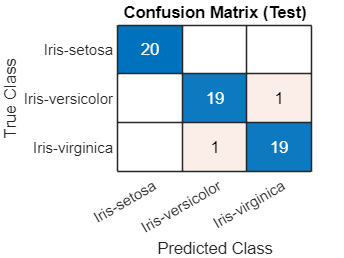

X_train = [x1_train; x2_train; x3_train];
Y_train = [ones(size(x1_train, 1), 1); ...
           2 * ones(size(x2_train, 1), 1); ...
           3 * ones(size(x3_train, 1), 1)];

IrisModel = fitcdiscr(X_train, Y_train);

X_test = [x1_test; x2_test; x3_test];
Y_test_true = [ones(size(x1_test, 1), 1); ...
               2 * ones(size(x2_test, 1), 1); ...
               3 * ones(size(x3_test, 1), 1)];


Y_test_pred = predict(IrisModel, X_test);

confusion_test = confusionmat(Y_test_true, Y_test_pred);
error_rate_test = 1 - sum(diag(confusion_test)) / sum(confusion_test(:));

class_labels = {'Iris-setosa', 'Iris-versicolor', 'Iris-virginica'};
figure;
confusionchart(confusion_test, class_labels);
title('Confusion Matrix (Test)');